# **drawBezier**

Draw 2-D Bezier curve.

## Description

The Bezier curve is a polynomal blending function which interpolates between the first and the last vertices ([1],[2]). The curve points are given by

$\left\langle x\left(t\right),y\left(t\right)\right\rangle =\sum_{k=1}^n \left\langle x_k ,y_k \right\rangle B_k \left(t\right)$,   $0\le t\le 1$

where $\left\langle x_k ,y_k \right\rangle$ are coordinates of *k*-th vertix, and $B_k \left(t\right)$are basis functions given by

$B_k \left(t\right)\equiv C_k^{n-1} t^k {\left(1-t\right)}^{n-1-k}$,    $k=1,\ldotp \ldotp \ldotp ,n-1$

## Syntax

drawBezier(xp,yp)

drawBezier(xp,yp,LineSpec)

drawBezier(xp,yp,'-np',np)

p = drawBezier(__)

### Description

drawBezier(xp,yp) draw Bezier curve with default number of points. 

drawBezier(xp,yp,LineSpec)  sets the line style, marker symbol, and color.

drawBezier(xp,yp,'-np',np) draw curve with np points.

p = drawBezier(__) returns structure with fields contain x-value and y-value for the curve.

### Method

For calculation of the coordinates of the curve **drawBezier **call function **evalBezier( xp, yp, t)  **which returns coordinates *x *and *y *of the curve at given values of parameter *t*.  Function **evalBezier **is based on subroutine BEZIER from [1]  (pp 225-226).  For usage of **evalBezier**, see Example 1.

## Arguments

### Input Arguments

**xp - **x-coordinate of polygon vertices (real vector)

**yp **- y-coordinate of polygon vertices (real vector)

xp, yp must be of the same size.

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve, np is scalar integer value > 2. Default: 100

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.x, p.y - points on curve

- p.xk, p.yk - key points: 1=start,2=end

- p.th - tangent angle in degrees: 1=start,2=end 

- p.color - line color

*Note*: p.x, p.y are row vectors if xp is row vector, and coulmn vectors if xp is coulmn vector.

## Examples

### Example 1

Example 5-3 from [1] (pp 143-144).

% coordinates of polygon vertices
xp=[1 2 4 3];
yp=[1 3 3 1];
% values from the book
tt = [0 0.15 0.35 0.5 0.65 0.85 1]; % parameter values
xt = [1, 1.5, 2.248, 2.75, 3.122, 3.248, 3];
yt = [1, 1.675, 2.367, 2.5, 2.36, 1.75, 1];
% calculate values for tt
[xb,yb]=evalBezier(xp,yp,tt);
% print coordinates and differences
fprintf('%4s%10s%10s%10s%10s\n','n','xb','aerr','yb','aerr');

   n        xb      aerr        yb      aerr


for n = 1:length(xb)
    fprintf('%4d%10f%10f%10f%10f\n',n,xb(n),xb(n)- xt(n),yb(n),yb(n)-yt(n));
end

   1  1.000000  0.000000  1.000000  0.000000
   2  1.504000  0.004000  1.765000  0.090000
   3  2.246000 -0.002000  2.365000 -0.002000
   4  2.750000  0.000000  2.500000  0.000000
   5  3.119000 -0.003000  2.365000  0.005000
   6  3.261000  0.013000  1.765000  0.015000
   7  3.000000  0.000000  1.000000  0.000000


### Example 2

figure
hold on
axis equal
% plot definiting polygon vertices
scatter(xp,yp,'r')
% plot definiting polygon
plot(xp,yp,'r')
% plot calculated points
scatter(xb,yb,'k','filled'); 
% draw curve
p = drawBezier(xp,yp)

p = struct with fields:
        x: [100×1 double]
        y: [100×1 double]
       xk: [1 3]
       yk: [1 1]
       th: [63.4349 -116.5651]
    color: 'k'


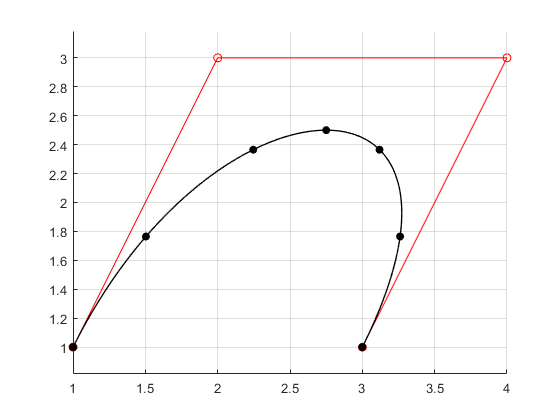

grid on

#### **Example 3**

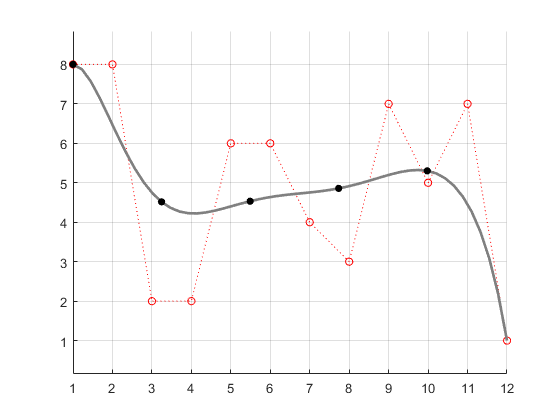

figure
axis equal
hold on
% coordinates of polygon vertices
nv = 12; % number of vertices
xv=1:nv; %randi(10,nv,1);
yv=randi(10,nv,1);
% plot vertices
scatter(xv,yv,30,'r')
% plot definiting polygon
plot(xv,yv,'r:')
% plot calculated points
% draw curve using 50 points in gray color
b = drawBezier(xv,yv,'-np',50,'LineWidth',2,'Color',[1 1 1]*0.5);
% label every 10th point
scatter(b.x(1:10:end),b.y(1:10:end),30,'k','filled')
grid on

#### **Example 4**

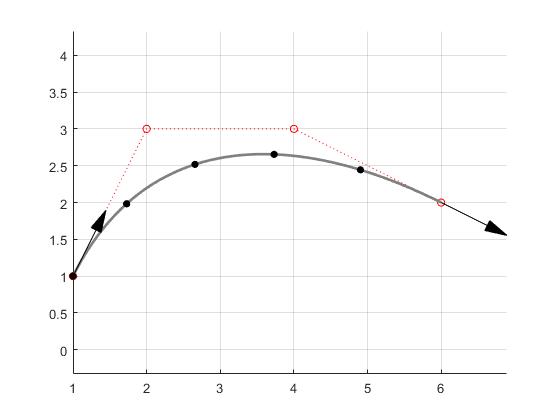

% intercept invaid data
figure
axis equal
hold on
% coordinates of polygon vertices
xv = [ 1 2 4 6];
yv = [ 1 3 3 2];
% plot vertices
scatter(xv,yv,30,'r')
% plot definiting polygon
plot(xv,yv,'r:')
% plot calculated points
% draw curve using 50 points in gray color
b = drawBezier(xv,yv,'-np',50,'LineWidth',2,'Color',[1 1 1]*0.5);
% label every 10th point
scatter(b.x(1:10:end),b.y(1:10:end),30,'k','filled')
drawArrow(3,0.3,0.3/2,xv(1),yv(1),'-rtheta',1,b.th(1),'k')
drawArrow(3,0.3,0.3/2,xv(4),yv(4),'-rtheta',1,b.th(2),'k')
grid on

## References

[1]  Rogers, Adams, *Mathematical elements for Computer Graphics*, McGraw-Hill,1976

[2] [WikipediA, Bezier curve](https://en.wikipedia.org/wiki/B%C3%A9zier_curve)